# Generate the kinematics for the Three-link 2D Biped

This function calculates the kinematics of the 3-link 2D biped. In particular, the position and velocities of the masses in an intertial frame. 

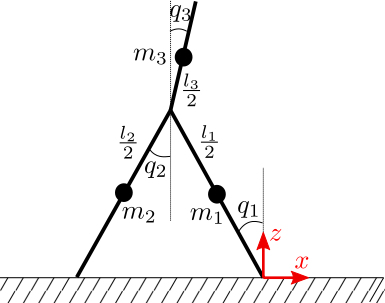

## The positions and velocities of the three masses $m_1$, $m_2$ , $m_3$:

syms x1 z1 x2 z2 x3 z3;
syms dx1 dz1 dx2 dz2 dx3 dz3;
syms q1 q2 q3;
syms dq1 dq2 dq3;
syms l1 l2 l3 

% write the symbolic formulas for x, z of masses m1, m2, m3:
x1 = 0.5*l1*sin(q1)

$$x1 = \frac{l_{1}\,\sin\left(q_{1}\right)}{2}$$

z1 = 0.5*l1*cos(q1)

$$z1 = \frac{l_{1}\,\cos\left(q_{1}\right)}{2}$$

x2 = 2*x1 - 0.5*l2*sin(q2)

$$x2 = l_{1}\,\sin\left(q_{1}\right)-\frac{l_{2}\,\sin\left(q_{2}\right)}{2}$$

z2 = 2*z1 - 0.5*l2*cos(q2)

$$z2 = l_{1}\,\cos\left(q_{1}\right)-\frac{l_{2}\,\cos\left(q_{2}\right)}{2}$$

x3 = 2*x1 + 0.5*l3*sin(q3)

$$x3 = l_{1}\,\sin\left(q_{1}\right)+\frac{l_{3}\,\sin\left(q_{3}\right)}{2}$$

z3 = 2*z1 + 0.5*l3*cos(q3)

$$z3 = l_{1}\,\cos\left(q_{1}\right)+\frac{l_{3}\,\cos\left(q_{3}\right)}{2}$$


% velocities of masses m1, m2, m3
dx1 = diff(x1, q1)*dq1

$$dx1 = \frac{{\mathrm{dq}}_{1}\,l_{1}\,\cos\left(q_{1}\right)}{2}$$

dz1 = diff(z1, q1)*dq1

$$dz1 = -\frac{{\mathrm{dq}}_{1}\,l_{1}\,\sin\left(q_{1}\right)}{2}$$

dx2 = diff(x2, q1)*dq1 + diff(x2, q2)*dq2

$$dx2 = {\mathrm{dq}}_{1}\,l_{1}\,\cos\left(q_{1}\right)-\frac{{\mathrm{dq}}_{2}\,l_{2}\,\cos\left(q_{2}\right)}{2}$$

dz2 = diff(z2, q1)*dq1 + diff(z2, q2)*dq2

$$dz2 = \frac{{\mathrm{dq}}_{2}\,l_{2}\,\sin\left(q_{2}\right)}{2}-{\mathrm{dq}}_{1}\,l_{1}\,\sin\left(q_{1}\right)$$

dx3 = diff(x3, q1)*dq1 + diff(x3, q3)*dq3

$$dx3 = {\mathrm{dq}}_{1}\,l_{1}\,\cos\left(q_{1}\right)+\frac{{\mathrm{dq}}_{3}\,l_{3}\,\cos\left(q_{3}\right)}{2}$$

dz3 = diff(z3, q1)*dq1 + diff(z3, q3)*dq3

$$dz3 = -{\mathrm{dq}}_{1}\,l_{1}\,\sin\left(q_{1}\right)-\frac{{\mathrm{dq}}_{3}\,l_{3}\,\sin\left(q_{3}\right)}{2}$$

## Positions and masses of other points of interest:

For the sake of visualization and later for control (e.g., foot-placement) we calculate the kinematics for some other points of interest as shown below:

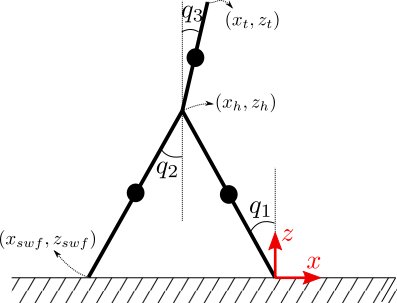

Variables definitions:

x_swf : Swing foot $x$-position

z_swf : Swing foot $y$-position

x_h : Hip $x$-position

z_h : Hip $y$-position

x_t : Torso top $x$-position

z_t : Torso top $y$-position

% Write the symbolic formulas for the hip, swing foot and torso end point
x_h     = l1*sin(q1)

$$x\_h = l_{1}\,\sin\left(q_{1}\right)$$

z_h     = l1*cos(q1)

$$z\_h = l_{1}\,\cos\left(q_{1}\right)$$


x_swf   = x_h - l2*sin(q2)

$$x\_swf = l_{1}\,\sin\left(q_{1}\right)-l_{2}\,\sin\left(q_{2}\right)$$

z_swf   = z_h - l2*cos(q2)

$$z\_swf = l_{1}\,\cos\left(q_{1}\right)-l_{2}\,\cos\left(q_{2}\right)$$


x_t     = x_h + l3*sin(q3)

$$x\_t = l_{1}\,\sin\left(q_{1}\right)+l_{3}\,\sin\left(q_{3}\right)$$

z_t     = z_h + l3*cos(q3)

$$z\_t = l_{1}\,\cos\left(q_{1}\right)+l_{3}\,\cos\left(q_{3}\right)$$

## Convert symbolic equations to MATLAB functions:

To convert your symbolic equations to MATLAB functions you can print out the symbolic formulas into a file (e.g., tmp.txt). Open tmp.txt and copy-paste the formulas to your MATLAB function (e.g. you may want to use these formulas in the visualize.m function).

tmp = fopen('tmp.txt', 'wt');
fprintf(tmp, '%s = %s;\n', 'x1', char(x1));
fprintf(tmp, '%s = %s;\n', 'z1', char(z1));
fprintf(tmp, '%s = %s;\n', 'x2', char(x2));
fprintf(tmp, '%s = %s;\n', 'z2', char(z2));
fprintf(tmp, '%s = %s;\n', 'x3', char(x3));
fprintf(tmp, '%s = %s;\n', 'z3', char(z3));
fprintf(tmp, '%s = %s;\n', 'x_h', char(x_h));
fprintf(tmp, '%s = %s;\n', 'z_h', char(z_h));
fprintf(tmp, '%s = %s;\n', 'x_t', char(x_t));
fprintf(tmp, '%s = %s;\n', 'z_t', char(z_t));
fprintf(tmp, '%s = %s;\n', 'x_swf', char(x_swf));
fprintf(tmp, '%s = %s;\n', 'z_swf', char(z_swf));
fclose(tmp);